Program to Calculate Wave Spectra

Author: Michael Noyce 

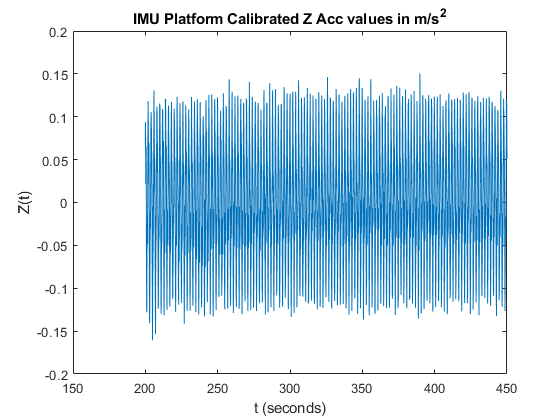

%Input SHARC-I IMU Data

IMUData = readtable('05Hz_20mm_reg.csv');
X_acc = IMUData{:, 2};
Y_acc = IMUData{:, 3};
Z_acc = IMUData{:, 4};
roll = IMUData{:, 5};
pitch = IMUData{:, 6};
yaw = IMUData{:, 7};

Fs = 100;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = height(IMUData(:, 4));             % Length of signal
t = (0:L-1)*T;        % Time vector

Z_acc_ms2 = Z_acc/16381.0; 

Z_acc_ms2_calibrated = ((Z_acc)-92.2236)/(1686.46) - 9.8172;

Z_acc_ms2_calibrated  = detrend(Z_acc_ms2_calibrated);

Z_acc_ms2_calibrated = lowpass(Z_acc_ms2_calibrated, 10, Fs);

plot(t(1, 20000:45000), Z_acc_ms2_calibrated(20000:45000, 1))
title('IMU Platform Calibrated Z Acc values in m/s^2')
xlabel('t (seconds)')
ylabel('Z(t)')



Z = fft(Z_acc_ms2_calibrated(20000:45000, 1))*Fs; %NB: Truncate to wave active periods before fft
L = length(Z);
P2 = abs(Z/L);
P1 = P2(1:L/2+1);

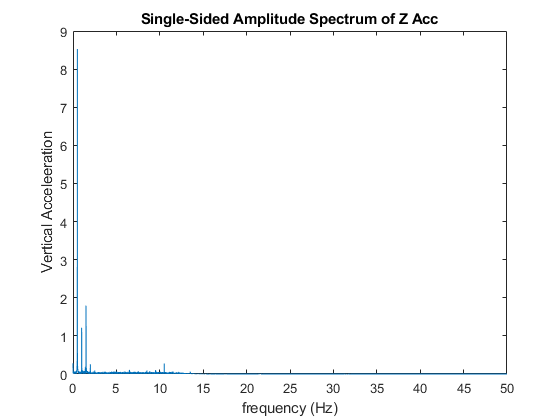

P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Z Acc')
xlabel('frequency (Hz)')
ylabel('Vertical Acceleeration')

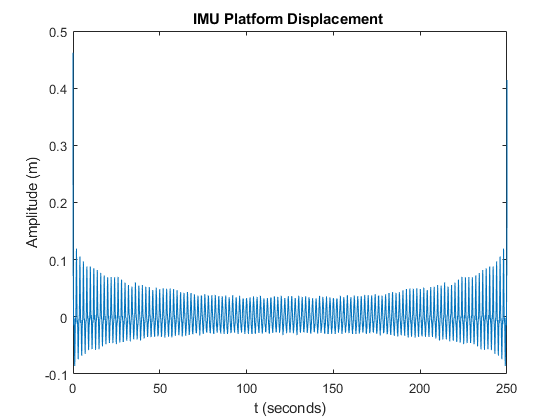


%%Wave Height Calculation
f1 = 0.02; %Lower corner frequency for half cosine taper
f2 = 0.03; %Upper frequency for half cosine taper
fc = 100; %Nyquist Frequency

for i = 1:length(f)
    if f < f1 
        P2(i, 1) = 0;
    end
        if f > f1 & f < f2
            P2(i, 1) = (1/2)*(1-cos(pi*(f-f1)/(f2-f1))*(-1/(2*pi*f^2)))*P2(i, 1);
        end
            if f > f2 & f < fc
                P2(i, 1) = -1/(2*pi*f^2)*P1(i,1); 
            end
end

waveHeightIMU = ifft(P2)*1/T;
t_trunc = (0:length(waveHeightIMU)-1)*T;
plot(t_trunc, waveHeightIMU)
title('IMU Platform Displacement ')
xlabel('t (seconds)')
ylabel('Amplitude (m)')


[pxx,f] = pwelch(waveHeightIMU, L/4, Fs);

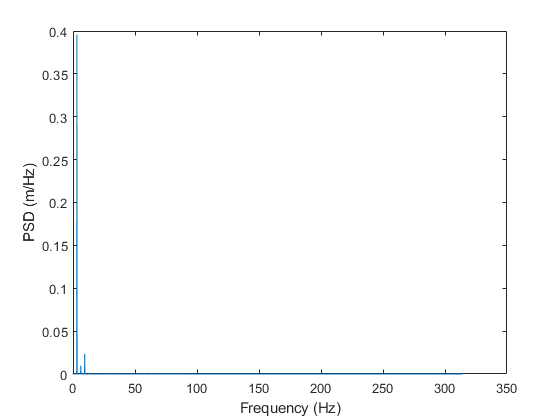


plot(f*100,pxx)
xlabel('Frequency (Hz)')
ylabel('PSD (m/Hz)')

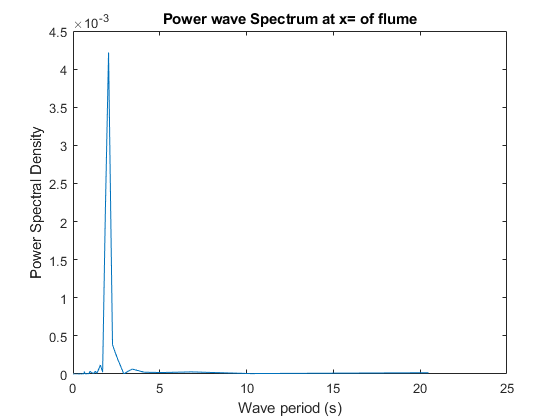


[height, period, TM1, TM10, HRMS] = spectral_analysis(t_trunc(10000:15000), waveHeightIMU(10000:15000), 4);

Functions

function [Hm0,Tp,Tm01,Tm_10,Hrms]=spectral_analysis(t,W,p)
%Function that builds the wave spectrum from a wave record (water elevation)
%and give some output parameters. The output parameters are the significant
%wave height and the mean wave period.
%It is based on Spectral.m Script (and Spectral2.m) reconverted into a
%function
%
% Input parameters
% t = time series input
% W = Water elevation series input
% p = number of periodograms
%
% Output parameters
% Hm0 = Spectral wave height/significant wave height = 4*sqrt(m0)
% HRMS = Root mean square wave height = sqrt(8*m0)
% Tp = peak wave period
% Tm01 = mean wave period = m0/m1
% Tm_10 = m_1/m0
%At: time interval between the results written on the table!
%At=t(2)-t(1);
At=(max(t)-min(t))/(length(t)-1);
%Sampling frequency
fr=1/At;

%Length of the water elevation record
n=length(W);
%number of periodograms
%p=10;
%p=5;
%W is divided into 20 samples/periodograms 18000/20=900 samples/periodogram
%W is divided into 10 periodograms 18000/10=1800 samples/peridogram
%W is divided into 5 periodograms 18000/5=3600 samples/periodogram
%Very long records needed!!! 90 min for 10 periodograms or 45 for 5.
%Periodogram samples
x=[];
for i=1:p
 x(:,i)=W((1+(i-1)*n/p):((n/p)*i));
end
%Next power of 2 greater or equal to length of the sample vector to
%calculate fft. FFT needs a length power of 2 to be efficient. For a
%shorter record, zeros will be added to reach this value.
nfft=2^(nextpow2(length(x(:,1))));
Pxx=[];
for i=1:p
%PSD
[Pxx(:,i),f]=periodogram(x(:,i),[],nfft,fr);
%[Pxx(:,i),w]=periodogram(x(:,i),[],nfft,fr);
end
%Average periodograms
mW=sum(Pxx,2)/p;
%f = Frequency vector
%f=w
%Wave period vector for the plot
ft=1./f;
%ft=1./w;
%Wave frequency spectral density plot
figure(2)
plot(f,mW)
xlabel('Frequency (Hz)')
ylabel('Power Spectral Density (m^2/Hz)')
title('Power wave Spectrum at x= of flume')
%Wave Spectral density plot with wave period
figure(3)
plot(ft,mW);
xlabel('Wave period (s)')
ylabel('Power Spectral Density')
title('Power wave Spectrum at x= of flume')
%Computation of some wave parameters.
%To do that 2 integrals must be numerically computed. Since the
%analytical function is unknown and the available data is a set of points
%(theorically equidistant), a Newton-Cotes quadrature will be used. 

%As the spectrum graph is built using linear interpolation, a composite
%trapezoidal rule will be used for numerical integration.
%Spectrum function E(f)=mW
%total number of points
m=length(mW);
%number of subintervals
m=m-1;
%length of the subinterval
Ax=(f(m+1)-f(1))/m;
%Integral I1 m0=int{E(f)df} I1
s=0;
for i=2:m
 s=s+mW(i); %sum(2,m) f(xi)
end
m0=0.5*Ax*(mW(1)+2*s +mW(m+1));
%Integral I2 m1=int{f*E(f)df} I2
s=0;
%f=f*E(f)=f*mW
for i=2:m
 s=s+f(i)*mW(i);
end
m1=0.5*Ax*(f(1)*mW(1)+2*s+f(m+1)*mW(m+1));
%Integral I3 m2=int{f^2*E(f)df} I3
s=0;
for i=2:m
 s=s+(f(i))^2*mW(i);
end
m2=0.5*Ax*((f(1))^2*mW(1)+2*s+(f(m+1))^2*mW(m+1));
%Integral I4 m_1=int{f^(-1)*E(f)df} I4
s=0;
for i=3:m
 s=s+mW(i)/f(i);
end
m_1=0.5*Ax*(1/f(2)*mW(2)+2*s+1/f(m+1)*mW(m+1));
%Note: f(1)=0 and so it is expluded. The integral is not fully computed.
%There is a mistake there!
%Spectrum analysis output
%Significant wave height
%Hm0=4*sqrt(int{E(f)df})
Hm0=4*sqrt(m0);
%Mean spectral wave period
%Tm01=(int{E(f)df}/(f*int{E(f)df}))
Tm01=m0/m1;
%Peak wave period
[M,i]=max(mW);
fm=f(i);
Tp=1/fm;
%Mean zero-crossing period
T0=sqrt(m0/m2);
%Mean spectral wave period Tm-1,0 with a higher weight of the longer waves
Tm_10=m_1/m0;
%Remember that one point has been ommited to compute Tm_10. I am not sure
%if it does not affect the result!
%Root Mean Square Wave height
Hrms=sqrt(2)/2*Hm0;
end